**Problem 1**

Red = x

Green = y

Blue = z

clear;        % Clears all variables in the workspace
clc;          % Clears the command window
close all;    % Closes all figure windows

set(groot, 'defaultTextInterpreter', 'latex');           % For text
set(groot, 'defaultLegendInterpreter', 'latex');         % For legends
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');  % For axis tick labels
set(groot, 'defaultColorbarTickLabelInterpreter', 'latex'); % For colorbar tick labels
set(groot, 'defaultTextFontSize', 12);                   % Default font size

syms theta_1 theta_2 theta_3 theta_4 theta_5 real
a1 = 50e-3;
a2 = 93e-3;
a3 = 93e-3;
a4 = 50e-3;
a5 = 45e-3;
a6 = 35e-3;

theta = [theta_1, theta_2, theta_3, theta_4, theta_5];
d = [a1,0,0,0,0];
a = [0,a2,a3,a4,a6];
alpha = [90,0,0,0,0];

A1_0 = dhTransform(theta(1), d(1), a(1), alpha(1))

$$A1\_0 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2_1 = dhTransform(theta(2),d(2),a(2),alpha(2))

$$A2\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \frac{93\,\cos\left(\theta_{2}\right)}{1000}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \frac{93\,\sin\left(\theta_{2}\right)}{1000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3_2 = dhTransform(theta(3),d(3),a(3),alpha(3))

$$A3\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{93\,\cos\left(\theta_{3}\right)}{1000}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \frac{93\,\sin\left(\theta_{3}\right)}{1000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4_3 = dhTransform(theta(4),d(4),a(4),alpha(4))

$$A4\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & \frac{\cos\left(\theta_{4}\right)}{20}\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & \frac{\sin\left(\theta_{4}\right)}{20}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T4_0 = simplify(A1_0*A2_1*A3_2*A4_3)

$$T4\_0 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1}\right) & -\sigma_{1}\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \frac{\cos\left(\theta_{1}\right)\,\sigma_{2}}{1000}\\ \sigma_{3}\,\sin\left(\theta_{1}\right) & -\sigma_{1}\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \frac{\sin\left(\theta_{1}\right)\,\sigma_{2}}{1000}\\ \sigma_{1} & \sigma_{3} & 0 & \frac{\sigma_{1}}{20}+\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}+\frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{2}=50\,\sigma_{3}+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right)\\ \sigma_{3}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

A5_4 = [1,0,0,a6-a4;
        0,1,0,a5;
        0,0,1,0;
        0,0,0,1];
T5_0 = simplify(T4_0*A5_4)

$$T5\_0 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1}\right) & -\sigma_{2}\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \frac{\cos\left(\theta_{1}\right)\,\sigma_{1}}{1000}\\ \sigma_{3}\,\sin\left(\theta_{1}\right) & -\sigma_{2}\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \frac{\sin\left(\theta_{1}\right)\,\sigma_{1}}{1000}\\ \sigma_{2} & \sigma_{3} & 0 & \frac{9\,\sigma_{3}}{200}+\frac{7\,\sigma_{2}}{200}+\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}+\frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=35\,\sigma_{3}-45\,\sigma_{2}+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right)\\ \sigma_{2}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

**Problem 2**

Decouple after first 3 joints: Oc is O3, 

First joint controls moves the direction of the arm, and is therefore partially responsible for x and y

% We can find theta_1 without doing any decoupling, since theta_1 is the
% only rotational joint in the x-y plane of the base frame
o4 = T4_0(1:3,4);
theta_1 = atan2(o4(2),o4(1));

% Since the robot is 4DOF, and w is given, we can rewrite the x and y
% component of x4_0 as a function of w
x4_0 = T4_0(1:3,1)

$$x4\_0 = \left(\begin{array}{c} \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}\right)$$

w = x4_0(3);
x4_0 = [sqrt(1-w^2)*cos(theta_1);
    sqrt(1-w^2)*sin(theta_1);
    w]

$$x4\_0 = \begin{array}{l} \left(\begin{array}{c} \frac{\cos\left(\theta_{1}\right)\,\sqrt{1-{\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}^{2}}\,\sigma_{1}}{\left|\cos\left(\theta_{1}\right)\,\sigma_{1}+\sin\left(\theta_{1}\right)\,\sigma_{1}\,\mathrm{i}\right|}\\ \frac{\sin\left(\theta_{1}\right)\,\sqrt{1-{\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}^{2}}\,\sigma_{1}}{\left|\cos\left(\theta_{1}\right)\,\sigma_{1}+\sin\left(\theta_{1}\right)\,\sigma_{1}\,\mathrm{i}\right|}\\ \sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=50\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right) \end{array}$$

% Kinematic decoupling
o3 = o4 - a(4)*x4_0;
oc = o3;

% Matlab says atan2(y,x). Which should i use? ----------------------

% Now we can find theta_2, 3 and 4
s = oc(3) - d(1);
r=sqrt(oc(1)^2+oc(2)^2);
c3 = (r^2 + s^2 - a(2)^2-a(3)^2)/(2*a(2)*a(3));

theta_3 = atan2(sqrt(1-c3^2), c3);
theta_2 = atan2(s,r) - atan2(a(3)*sin(atan2(c3,sqrt(1-c3^2))),a(2)+a(3)*c3);

% Isolate theta_4 from w
theta_4 = asin(w) - (theta_2 + theta_3);


Use problem 3 to check problem 2. They should line up

R=32e-3;
pc_0=[150e-3;0;120e-3];

o4 = pc_0+R*[0;cos(0);sin(0)]

o4 =     0.1500
    0.0320
    0.1200



[q1,q2,q3,q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3)

q1 = 0.2102

q2 = 1.4302

q3 = -1.6699

q4 = 0.2397

T4_0_f = matlabFunction(T4_0);

T4_0_f(q1,q2,q3,q4)

ans =     0.9780         0    0.2086    0.1500
    0.2086         0   -0.9780    0.0320
         0    1.0000         0    0.1200
         0         0         0    1.0000


**Problem 3**

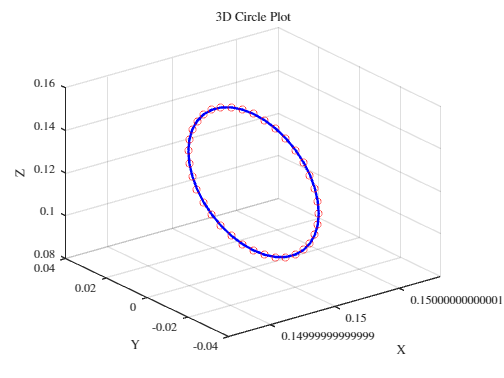

angles = linspace(0,2*pi,37);

x_circle = pc_0(1) * ones(size(angles));
y_circle = R * cos(angles) + pc_0(2); 
z_circle = R * sin(angles) + pc_0(3);

o4_matrix = [x_circle; y_circle; z_circle];
num_points = size(o4_matrix, 2); 

for i = 1:num_points
    o4 = o4_matrix(:, i); 
    [q1, q2, q3, q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3);
    
    q1_all(i) = q1;
    q2_all(i) = q2;
    q3_all(i) = q3;
    q4_all(i) = q4;

    FK = T4_0_f(q1_all(i),q2_all(i),q3_all(i),q4_all(i));
    
    FK_points(:,i) = FK(1:3,4);

    FK_r = FK(1:3,3);
  
end

figure(1)
plot3(FK_points(1,:),FK_points(2,:),FK_points(3,:),'ro')
hold on
plot3(x_circle, y_circle, z_circle, '-b', 'LineWidth', 2); 
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z'); %test
title('3D Circle Plot');

**Problem 4**


T1_0 = simplify(A1_0);
T2_0 = simplify(A1_0*A2_1);
T3_0 = simplify(A1_0*A2_1*A3_2);

o0_j = [0,0,0]';
o1_j = T1_0(1:3,4);
o2_j = T2_0(1:3,4);
o3_j = T3_0(1:3,4);
o4_j = T4_0(1:3,4);
o5_j = T5_0(1:3,4);

o_j_matrix4 = [o0_j, o1_j, o2_j, o3_j, o4_j];
o_j_matrix5 = [o0_j, o1_j, o2_j, o3_j, o5_j];

z0_j = [0,0,1]';
z1_j = T1_0(1:3,3);
z2_j = T2_0(1:3,3);
z3_j = T3_0(1:3,3);
z4_j = T4_0(1:3,3);

z_j_matrix4 = [z0_j, z1_j, z2_j, z3_j];
z_j_matrix5 = [z0_j, z1_j, z2_j, z4_j];


J4 = simplify(Jacobi_Revolute(o_j_matrix4, z_j_matrix4, 5));

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{2} & -\cos\left(\theta_{1}\right)\,\sigma_{4} & -\cos\left(\theta_{1}\right)\,\left(\frac{\sigma_{6}}{20}+\sigma_{7}\right) & -\frac{\sigma_{6}\,\cos\left(\theta_{1}\right)}{20}\\ \sigma_{3} & -\sin\left(\theta_{1}\right)\,\sigma_{4} & -\sin\left(\theta_{1}\right)\,\left(\frac{\sigma_{6}}{20}+\sigma_{7}\right) & -\frac{\sigma_{6}\,\sin\left(\theta_{1}\right)}{20}\\ 0 & \frac{{\cos\left(\theta_{1}\right)}^{2}\,\sigma_{5}}{1000}+\frac{{\sin\left(\theta_{1}\right)}^{2}\,\sigma_{5}}{1000} & -\sin\left(\theta_{1}\right)\,\left(\frac{93\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{1000}-\sigma_{2}\right)-\cos\left(\theta_{1}\right)\,\left(\frac{93\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{1000}-\sigma_{3}\right) & -\cos\left(\theta_{1}\right)\,\left(\frac{93\,\cos\left(\theta_{1}\right)\,\sigma_{1}}{1000}-\sigma_{3}\right)-\sin\left(\theta_{1}\right)\,\left(\frac{93\,\sin\left(\theta_{1}\right)\,\sigma_{1}}{1000}-\sigma_{2}\right)\\ 0 & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{2}\right)\\ \sigma_{2}=\frac{\sin\left(\theta_{1}\right)\,\sigma_{5}}{1000}\\ \sigma_{3}=\frac{\cos\left(\theta_{1}\right)\,\sigma_{5}}{1000}\\ \sigma_{4}=\frac{\sigma_{6}}{20}+\sigma_{7}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}\\ \sigma_{5}=50\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right)\\ \sigma_{6}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{7}=\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000} \end{array}$$

J5 = Jacobi_Revolute(o_j_matrix5, z_j_matrix5, 5);

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{2} & -\cos\left(\theta_{1}\right)\,\sigma_{4} & -\cos\left(\theta_{1}\right)\,\sigma_{5} & -\cos\left(\theta_{1}\right)\,\sigma_{6}\\ \sigma_{3} & -\sin\left(\theta_{1}\right)\,\sigma_{4} & -\sin\left(\theta_{1}\right)\,\sigma_{5} & -\sin\left(\theta_{1}\right)\,\sigma_{6}\\ 0 & \frac{{\cos\left(\theta_{1}\right)}^{2}\,\sigma_{7}}{1000}+\frac{{\sin\left(\theta_{1}\right)}^{2}\,\sigma_{7}}{1000} & -\cos\left(\theta_{1}\right)\,\left(\frac{93\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{1000}-\sigma_{3}\right)-\sin\left(\theta_{1}\right)\,\left(\frac{93\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{1000}-\sigma_{2}\right) & -\cos\left(\theta_{1}\right)\,\left(\frac{93\,\cos\left(\theta_{1}\right)\,\sigma_{1}}{1000}-\sigma_{3}\right)-\sin\left(\theta_{1}\right)\,\left(\frac{93\,\sin\left(\theta_{1}\right)\,\sigma_{1}}{1000}-\sigma_{2}\right)\\ 0 & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{2}\right)\\ \sigma_{2}=\frac{\sin\left(\theta_{1}\right)\,\sigma_{7}}{1000}\\ \sigma_{3}=\frac{\cos\left(\theta_{1}\right)\,\sigma_{7}}{1000}\\ \sigma_{4}=\frac{9\,\sigma_{10}}{200}+\frac{7\,\sigma_{9}}{200}+\sigma_{8}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}\\ \sigma_{5}=\frac{9\,\sigma_{10}}{200}+\frac{7\,\sigma_{9}}{200}+\sigma_{8}\\ \sigma_{6}=\frac{9\,\sigma_{10}}{200}+\frac{7\,\sigma_{9}}{200}\\ \sigma_{7}=35\,\sigma_{10}-45\,\sigma_{9}+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right)\\ \sigma_{8}=\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000}\\ \sigma_{9}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{10}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$


J4_f = matlabFunction(J4);
J5_f = matlabFunction(J5);

q1_0 = q1_all(1);
q2_0 = q2_all(1);
q3_0 = q3_all(1);
q4_0 = q4_all(1);

q1_90 = q1_all(10);
q2_90 = q2_all(10);
q3_90 = q3_all(10);
q4_90 = q4_all(10);

q1_180 = q1_all(19);
q2_180 = q2_all(19);
q3_180 = q3_all(19);
q4_180 = q4_all(19);

q1_270 = q1_all(28);
q2_270 = q2_all(28);
q3_270 = q3_all(28);
q4_270 = q4_all(28);


% NOT USED TILL Q6 %
q1_360 = q1_all(37);
q2_360 = q2_all(37);
q3_360 = q3_all(37);
q4_360 = q4_all(37);
% ---------------- %


J4_0 = J4_f(q1_0,q2_0,q3_0,q4_0);
J4_90 = J4_f(q1_90,q2_90,q3_90,q4_90);
J4_180 = J4_f(q1_180,q2_180,q3_0,q4_180);
J4_270 = J4_f(q1_270,q2_270,q3_270,q4_270);

% NOT USED TILL Q5
J4_360 = J4_f(q1_360,q2_360,q3_360,q4_360);

J5_0 = J5_f(q1_0,q2_0,q3_0,q4_0);
J5_90 = J5_f(q1_90,q2_90,q3_90,q4_90);
J5_180 = J5_f(q1_180,q2_180,q3_0,q4_180);
J5_270 = J5_f(q1_270,q2_270,q3_270,q4_270);



**Problem 5**

q0 = [q1_0, q2_0, q3_0, q4_0];
q1 = [q1_90, q2_90, q3_90, q4_90];
q2 = [q1_180, q2_180, q3_180, q4_180];
q3 = [q1_270, q2_270, q3_270, q4_270];
q4 = [q1_360, q2_360, q3_360, q4_360];


T_problem(:,:,1) = T4_0_f(q0(1),q0(2),q0(3),q0(4));
T_problem(:,:,2) = T4_0_f(q1(1),q1(2),q1(3),q1(4));
T_problem(:,:,3) = T4_0_f(q2(1),q2(2),q2(3),q2(4));
T_problem(:,:,4) = T4_0_f(q3(1),q3(2),q3(3),q3(4));
T_problem(:,:,5) = T4_0_f(q4(1),q4(2),q4(3),q4(4));

v = [0, 0, 0, 0;
    0, -27e-3, 0 ,0;
    0, 0, -27e-3, 0;
    0, 27e-3, 0, 0;
    0,0,0,0];

JJ(:,:,1) = J4_0;
JJ(:,:,2) = J4_90;
JJ(:,:,3) = J4_180;
JJ(:,:,4) = J4_270;
JJ(:,:,5) = J4_360;

for i = 1:5

    Ryx = T_problem(2,1,i);
    Rxx = T_problem(1,1,i);
    Mask = [1,0,0,0,0,0;
            0,1,0,0,0,0;
            0,0,1,0,0,0;
            0,0,0,Ryx, -Rxx, 0];
    A4x6 = JJ(:,:,i);
    A4x4 = Mask*JJ(:,:,i);
    J_plus = ((transpose(A4x4)*A4x4)^-1)*transpose(A4x4);     % Underactuated arm (4 DOF < 6 DOF)
    q_dot(:,i) = J_plus*v(i,:)';

end


q_dot

q_dot =          0   -0.1800    0.0000    0.1800         0
         0    0.0000   -0.0693    0.0000         0
         0   -0.0000   -0.2196   -0.0000         0
         0    0.0000    0.2889    0.0000         0


**Problem 6**



q0d = q_dot(:,1)';
q0dd = [0,0,0,0];


q1d = q_dot(:,2)';
q1dd = [0,0,0,0];


q2d = q_dot(:,3)';
q2dd = [0,0,0,0];


q3d = q_dot(:,4)';
q3dd = [0,0,0,0];


q4d = q_dot(:,5)';
q4dd = [0,0,0,0];



t0 = 0;
t1 = 2;

C_0 = Trajectory_interpolation(t0, t1, q0, q0d, q0dd, q1, q1d, q1dd);
C_90 = Trajectory_interpolation(t0, t1, q1, q1d, q1dd, q2, q2d, q2dd);
C_180 = Trajectory_interpolation(t0, t1, q2, q2d, q2dd, q3, q3d, q3dd);
C_270 = Trajectory_interpolation(t0, t1, q3, q3d, q3dd, q4, q4d, q4dd);


**Problem 7**

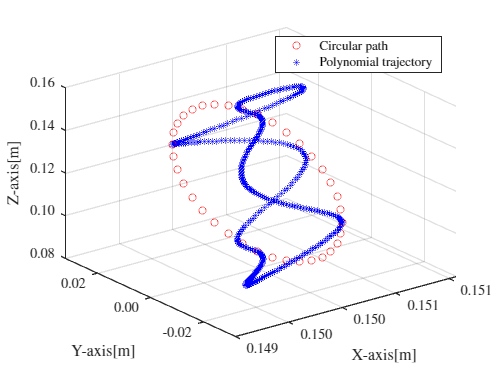

num_points_7 = 100;
t = linspace(0,2,num_points_7);
q_0_1 = C_0(1,1)+C_0(1,2)*t+C_0(1,3)*t.^2+C_0(1,4)*t.^3+C_0(1,5)*t.^4+C_0(1,6)*t.^5;
q_0_2 = C_0(2,1)+C_0(2,2)*t+C_0(2,3)*t.^2+C_0(2,4)*t.^3+C_0(2,5)*t.^4+C_0(2,6)*t.^5;
q_0_3 = C_0(3,1)+C_0(3,2)*t+C_0(3,3)*t.^2+C_0(3,4)*t.^3+C_0(3,5)*t.^4+C_0(3,6)*t.^5;
q_0_4 = C_0(4,1)+C_0(4,2)*t+C_0(4,3)*t.^2+C_0(4,4)*t.^3+C_0(4,5)*t.^4+C_0(4,6)*t.^5;

q_90_1 = C_90(1,1)+C_90(1,2)*t+C_90(1,3)*t.^2+C_90(1,4)*t.^3+C_90(1,5)*t.^4+C_90(1,6)*t.^5;
q_90_2 = C_90(2,1)+C_90(2,2)*t+C_90(2,3)*t.^2+C_90(2,4)*t.^3+C_90(2,5)*t.^4+C_90(2,6)*t.^5;
q_90_3 = C_90(3,1)+C_90(3,2)*t+C_90(3,3)*t.^2+C_90(3,4)*t.^3+C_90(3,5)*t.^4+C_90(3,6)*t.^5;
q_90_4 = C_90(4,1)+C_90(4,2)*t+C_90(4,3)*t.^2+C_90(4,4)*t.^3+C_90(4,5)*t.^4+C_90(4,6)*t.^5;

q_180_1 = C_180(1,1) + C_180(1,2) * t + C_180(1,3) * t.^2 + C_180(1,4) * t.^3 + C_180(1,5) * t.^4 + C_180(1,6) * t.^5;
q_180_2 = C_180(2,1) + C_180(2,2) * t + C_180(2,3) * t.^2 + C_180(2,4) * t.^3 + C_180(2,5) * t.^4 + C_180(2,6) * t.^5;
q_180_3 = C_180(3,1) + C_180(3,2) * t + C_180(3,3) * t.^2 + C_180(3,4) * t.^3 + C_180(3,5) * t.^4 + C_180(3,6) * t.^5;
q_180_4 = C_180(4,1) + C_180(4,2) * t + C_180(4,3) * t.^2 + C_180(4,4) * t.^3 + C_180(4,5) * t.^4 + C_180(4,6) * t.^5;

q_270_1 = C_270(1,1) + C_270(1,2) * t + C_270(1,3) * t.^2 + C_270(1,4) * t.^3 + C_270(1,5) * t.^4 + C_270(1,6) * t.^5;
q_270_2 = C_270(2,1) + C_270(2,2) * t + C_270(2,3) * t.^2 + C_270(2,4) * t.^3 + C_270(2,5) * t.^4 + C_270(2,6) * t.^5;
q_270_3 = C_270(3,1) + C_270(3,2) * t + C_270(3,3) * t.^2 + C_270(3,4) * t.^3 + C_270(3,5) * t.^4 + C_270(3,6) * t.^5;
q_270_4 = C_270(4,1) + C_270(4,2) * t + C_270(4,3) * t.^2 + C_270(4,4) * t.^3 + C_270(4,5) * t.^4 + C_270(4,6) * t.^5;
for i=1:num_points_7
    FK_0 = T4_0_f(q_0_1(i),q_0_2(i),q_0_3(i),q_0_4(i));
    FK_points_0(:,i) = FK_0(1:3,4);
    FK_90 = T4_0_f(q_90_1(i),q_90_2(i),q_90_3(i),q_90_4(i));
    FK_points_90(:,i) = FK_90(1:3,4);
    FK_180 = T4_0_f(q_180_1(i), q_180_2(i), q_180_3(i), q_180_4(i));
    FK_points_180(:, i) = FK_180(1:3, 4);
    FK_270 = T4_0_f(q_270_1(i), q_270_2(i), q_270_3(i), q_270_4(i));
    FK_points_270(:, i) = FK_270(1:3, 4);
end


figure(2)
plot3(FK_points(1,:),FK_points(2,:),FK_points(3,:),'ro')
hold on;
plot3(FK_points_0(1,:),FK_points_0(2,:),FK_points_0(3,:),'*b')
hold on;
plot3(FK_points_90(1,:),FK_points_90(2,:),FK_points_90(3,:),'*b')
hold on;
plot3(FK_points_180(1,:),FK_points_180(2,:),FK_points_180(3,:),'*b')
hold on;
plot3(FK_points_270(1,:),FK_points_270(2,:),FK_points_270(3,:),'*b')
legend('Circular path','Polynomial trajectory', 'Location', 'best','FontSize', 11);
hold off
xlabel('X-axis[m]','FontSize', 12);
ylabel('Y-axis[m]','FontSize', 12);
zlabel('Z-axis[m]','FontSize', 12);
ytickformat('%.2f')
xtickformat('%.3f')
ztickformat('%.2f')
ax = gca;        
ax.FontSize = 12;
grid on;

**Problem 7 more knot points**

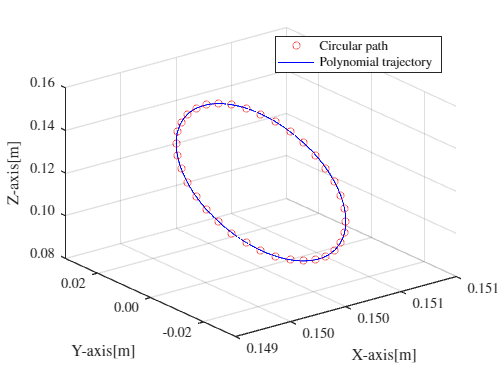

angles_7 = linspace(0,2*pi,360);

x_circle = pc_0(1) * ones(size(angles_7));
y_circle = R * cos(angles_7) + pc_0(2); 
z_circle = R * sin(angles_7) + pc_0(3);

o4_matrix = [x_circle; y_circle; z_circle];
num_points_7 = size(o4_matrix, 2); 

for i = 1:num_points_7
    o4 = o4_matrix(:, i); 
    [q1, q2, q3, q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3);
    q1_7(i) = q1;
    q2_7(i) = q2;
    q3_7(i) = q3;
    q4_7(i) = q4;
end
q_7 = [q1_7;q2_7;q3_7;q4_7];
Fk_7 = zeros(3,10,num_points_7);
for i = 2:num_points_7-1
    Fk_7(:,:,i) = Q_7(8, num_points_7, q_7(:,i), [0,0,0,0], q_7(:,i+1), [0,0,0,0], 10, T4_0, J4, 27e-3, 27e-3,angles_7(i)*180/pi,angles_7(i+1)*180/pi);
end
Fk_7(:,:,1) = Q_7(8, num_points_7, q_7(:,1), [0,0,0,0], q_7(:,2), [0,0,0,0], 10, T4_0, J4, 0, 27e-3,angles_7(1)*180/pi,angles_7(2)*180/pi);
Fk_7(:,:,360) = Q_7(8, num_points_7, q_7(:,359), [0,0,0,0], q_7(:,360), [0,0,0,0], 10, T4_0, J4, 27e-3, 0,angles_7(359)*180/pi,angles_7(360)*180/pi);

figure(7);

% Clear the figure to start fresh
clf;
plot3(FK_points(1,:),FK_points(2,:),FK_points(3,:),'ro');
hold on
% Loop through slices of Fk_7
for i = 1:num_points_7
    % Extract x, y, z for the i-th slice
    x = Fk_7(1, :, i);
    y = Fk_7(2, :, i);
    z = Fk_7(3, :, i);
    
    % Plot the points for this iteration
    plot3(x, y, z, '-b');
    
    % Hold on to overlay plots from each iteration
    hold on;
end

% Add labels and grid
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;

% Release hold after all iterations
hold off;
% Add labels and grid for better visualization
xlabel('X-axis[m]',"FontSize",12);
ylabel('Y-axis[m]',"FontSize",12);
zlabel('Z-axis[m]',"FontSize",12);
legend('Circular path','Polynomial trajectory',"Location","best",'FontSize',11);
ytickformat('%.2f');
xtickformat('%.3f');
ztickformat('%.2f');
ax = gca;        
ax.FontSize = 12;
xlim([0.149,0.151]);
grid on;
hold off; % Release hold after all iterations

**Problem 8**

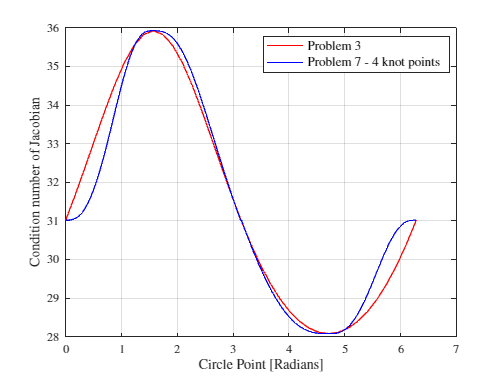


% Initialize array to store condition numbers
cond_values = zeros(1, num_points);

% Calculate condition numbers for each point
for i = 1:num_points
    cond_values(i) = cond(J4_f(q1_all(i), q2_all(i), q3_all(i), q4_all(i)));
end


for i = 1:100
    cond_values_7_1(i) = cond(J4_f(q_0_1(i), q_0_2(i), q_0_3(i), q_0_4(i)));
    cond_values_7_2(i) = cond(J4_f(q_90_1(i), q_90_2(i), q_90_3(i), q_90_4(i)));
    cond_values_7_3(i) = cond(J4_f(q_180_1(i), q_180_2(i), q_180_3(i), q_180_4(i)));
    cond_values_7_4(i) = cond(J4_f(q_270_1(i), q_270_2(i), q_270_3(i), q_270_4(i)));
end

cond_values_7_tot = [cond_values_7_1,cond_values_7_2,cond_values_7_3,cond_values_7_4];
% for i = 1:num_points_7
%     cond_values_7_mk(i) = cond(J4_f(q_7(1,i),q_7(2,i),q_7(3,i),q_7(4,i)));
% end

figure(4)
plot(angles, cond_values, 'r')
hold on
plot(linspace(0,2*pi,100*4), cond_values_7_tot, 'b')
% hold on
% plot(angles_7,cond_values_7_mk,'k')
hold off
xlabel("Circle Point [Radians]","FontSize",12);
ylabel("Condition number of Jacobian","FontSize",12);
legend('Problem 3','Problem 7 - 4 knot points',"Location","best","FontSize",11);
grid on;

**Problem 9**

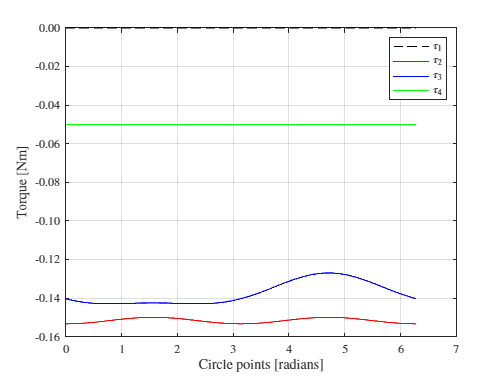


angles_9 = linspace(0,2*pi,360);

x_circle = pc_0(1) * ones(size(angles_9));
y_circle = R * cos(angles_9) + pc_0(2); 
z_circle = R * sin(angles_9) + pc_0(3);

o4_matrix = [x_circle; y_circle; z_circle];
num_points_9 = size(o4_matrix, 2); 





for i = 1:num_points_9
    o4 = o4_matrix(:, i); 
    [q1, q2, q3, q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3);
    
    q1_9(i) = q1;
    q2_9(i) = q2;
    q3_9(i) = q3;
    q4_9(i) = q4;

    F = [0,0,-1,0,0,0]';
    J4_9 = J4_f(q1_9(i),q2_9(i),q3_9(i),q4_9(i));
    
    tau(:,i) = J4_9'*F;

end

figure(5)

plot(angles_9, tau(1,:), '--k', "DisplayName", "$\tau_1$")
hold on
plot(angles_9, tau(2,:), 'r', "DisplayName", "$\tau_2$")
hold on
plot(angles_9, tau(3,:), 'b', "DisplayName", "$\tau_3$")
hold on
plot(angles_9, tau(4,:), 'g', "DisplayName", "$\tau_4$")
hold off
xlabel('Circle points [radians]',"FontSize",12);
ylabel('Torque [Nm]',"FontSize",12);
grid on;
ytickformat('%.2f');
legend show


% for i = 1:num_points_9
%  
%     tau_11(i) = 0;
%     tau_22(i) = -1*(a(2)*cos(q2_9(i)) + a(3)*cos(q2_9(i) + q3_9(i)) + a(4)*cos(q2_9(i) + q3_9(i) + q4_9(i)));
%     tau_33(i) = -1*(a(3)*cos(q2_9(i) + q3_9(i)) + a(4)*cos(q2_9(i) + q3_9(i) + q4_9(i)));
%     tau_44(i) = -1*(a(4)*cos(q2_9(i) + q3_9(i) + q4_9(i)));
% 
% end
% 
% 
% 
% figure(6)
% 
% plot(angles_9, tau_11, '--k', "DisplayName", "$\tau_1$")
% hold on
% plot(angles_9, tau_22, 'r', "DisplayName", "$\tau_2$")
% hold on
% plot(angles_9, tau_33, 'b', "DisplayName", "$\tau_3$")
% hold on
% plot(angles_9, tau_44, 'g', "DisplayName", "$\tau_4$")
% hold off
% ytickformat('%.2f');
% legend show

**Problem 10**

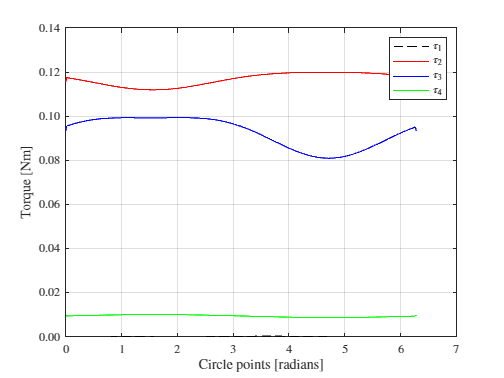


syms dq1 dq2 dq3 dq4 ddq1 ddq2 ddq3 ddq4 real

R10(:,:,1) = T1_0(1:3,1:3);
R10(:,:,2) = T2_0(1:3,1:3);
R10(:,:,3) = T3_0(1:3,1:3);
R10(:,:,4) = T4_0(1:3,1:3);


I_0 = 0.5 * 0.06 * (a(1)^2 + 0.035^2) + 0.06 * 0.005^2;

I(:,:,1) = [I_0, 0, 0;
            0 , 0.4 * I_0, 0;
            0 , 0, 0.9*I_0];
I(:,:,2) = [0.45*I_0, 0, 0;
            0 , 1.4*I_0, 0;
            0 , 0, 1.2*I_0];
I(:,:,3) = [0.45*I_0, 0, 0;
            0 , 1.4*I_0, 0;
            0 , 0, 1.2*I_0];
I(:,:,4) = [0.5*I_0, 0, 0;
            0 , 0.5*I_0, 0;
            0 , 0, 0.5*I_0];


m = [0.06 + 0.08 + 0.08 + 0.04, 
    0.08 + 0.08 + 0.04, 
    0.08 + 0.04, 
    0.04];



%%%%%%%% qd(i) are found below %%%%%%%%%%%%

q_10 = [q1_9;q2_9;q3_9;q4_9];
Q_10d = zeros(4,360);
for i = 2:num_points_9-1
    [Q_10d(:,i),~] = Q_10(8, num_points_9, q_10(:,i), [0,0,0,0], q_10(:,i+1), [0,0,0,0], 10, T4_0, J4, 27e-3, 27e-3,angles_9(i),angles_9(i+1));
end
[Q_10d(:,1),~] = Q_10(8, num_points_9, q_10(:,1), [0,0,0,0], q_10(:,2), [0,0,0,0], 10, T4_0, J4, 0, 27e-3,angles_9(1),angles_9(2));
[~,Q_10d(:,360)] = Q_10(8, num_points_9, q_10(:,359), [0,0,0,0], q_10(:,360), [0,0,0,0], 10, T4_0, J4, 27e-3, 0,angles_9(359),angles_9(360));

q1d = Q_10d(1,:);
q2d = Q_10d(2,:);
q3d = Q_10d(3,:);
q4d = Q_10d(4,:);


%%%%%%%% D is found below %%%%%%%%%%%%

D_sum = zeros(4, 4);

for j = 1:4

    D = m(j) * J4(1:3,:)' * J4(1:3,:) + J4(4:6,:)' * R10(:,:,j) * I(:,:,j) * R10(:,:,j)' * J4(4:6,:);
    
    D_sum = D_sum + D;

end

D_q = D_sum;

ddq = [ddq1; ddq2; ddq3; ddq4];

dd_sum = D * ddq;

dd_sum_f = matlabFunction(dd_sum);

dd_sum_f(1,2,3,4,5,6,7,8);

%%%%%%%% c is found below %%%%%%%%%%%%


for i = 1:4
    for j = 1:4
        for k = 1:4
            
            d_dkj_dqi = diff(D_q(k, j), theta(i));
            d_dki_dqj = diff(D_q(k, i), theta(j));
            d_dij_dqk = diff(D_q(i, j), theta(k));
            
            c(i, j, k) = 0.5 * (d_dkj_dqi + d_dki_dqj - d_dij_dqk);
        end
    end
end

q_dot = [dq1; dq2; dq3; dq4];  

result_vector = sym(zeros(4, 1)); 

for k = 1:4
    sum_result = 0;  
    for i = 1:4
        for j = 1:4
            sum_result = sum_result + c(i, j, k) * q_dot(i) * q_dot(j);
        end
    end
    
    result_vector(k) = sum_result;
end

cc_sum = result_vector;

cc_sum_f = matlabFunction(cc_sum);


for i=1:num_points_9

    SUM2(:,i) = cc_sum_f(q1_9(i),q2_9(i),q3_9(i),q4_9(i),q1d(i),q2d(i),q3d(i),q4d(i));

end


%%%%%%%% g is found below %%%%%%%%%%%%

g = 9.8;

r_c = [a(1)-0.02, a(2)-0.03, a(3)-0.03, a(4)-0.025];

% for i = 1:num_points_9
% 
%     g_1(i) = 0;
% 
%     g_2(i) = g*m(4)*((a(2)*cos(q2_9(i)) + a(3)*cos(q2_9(i) + q3_9(i)) + r_c(4)*cos(q2_9(i) + q3_9(i) + q4_9(i)))) + ...
%              g*m(3)*((a(2)*cos(q2_9(i)) + r_c(3)*cos(q2_9(i) + q3_9(i)))) + ...
%              g*m(2)*(r_c(2)*cos(q2_9(i)));
% 
%     g_3(i) = g*m(4)*(a(3)*cos(q2_9(i) + q3_9(i)) + r_c(4)*cos(q2_9(i) + q3_9(i) + q4_9(i))) + ...
%              g*m(3)*r_c(3)*cos(q2_9(i) + q3_9(i));
% 
%     g_4(i) = g*m(4)*r_c(4)*cos(q2_9(i) + q3_9(i) + q4_9(i));
% 
% end

for i = 1:num_points_9
 
    g_1(i) = 0;

    g_2(i) = 0.158760*cos(q2_9(i)) + 0.085848*cos(q2_9(i) + q3_9(i)) + 0.009800*cos(q2_9(i) + q3_9(i) + q4_9(i));
    
    g_3(i) = 0.085848*cos(q2_9(i) + q3_9(i)) + 0.009800*cos(q2_9(i) + q3_9(i) + q4_9(i));
    
    g_4(i) = 0.009800*cos(q2_9(i) + q3_9(i) + q4_9(i));

end

SUM3 = [g_1; g_2; g_3; g_4];






tau_10 = SUM2 + SUM3;

figure(7)

plot(angles_9, tau_10(1,:), '--k', "DisplayName", "$\tau_1$")
hold on
plot(angles_9, tau_10(2,:), 'r', "DisplayName", "$\tau_2$")
hold on
plot(angles_9, tau_10(3,:), 'b', "DisplayName", "$\tau_3$")
hold on
plot(angles_9, tau_10(4,:), 'g', "DisplayName", "$\tau_4$")
hold off
ylabel('Torque [Nm]',"FontSize",12);
xlabel('Circle points [radians]',"FontSize",12)
ytickformat('%.2f');
grid on;
ylim([0, 0.14])
legend show